clear;
tic;

% Load training set images
source_dir = 1:2;
% Initialize train and test counts
train_count = 1:2007; 
test_count = 2008:2107;

% Display the train and test counts
disp('Train count:');

Train count:


disp(train_count);

           1           2           3           4           5           6           7           8           9          10          11          12          13          14          15          16          17          18          19          20          21          22          23          24          25          26          27          28          29          30          31          32          33          34          35          36          37          38          39          40          41          42          43          44          45          46          47          48          49          50          51          52          53          54          55          56          57          58          59          60          61          62          63          64          65          66          67          68          69          70          71          72          73          74          75          76          77          78          79          80          81          82          83    

disp('Test count:');

Test count:


disp(test_count);

        2008        2009        2010        2011        2012        2013        2014        2015        2016        2017        2018        2019        2020        2021        2022        2023        2024        2025        2026        2027        2028        2029        2030        2031        2032        2033        2034        2035        2036        2037        2038        2039        2040        2041        2042        2043        2044        2045        2046        2047        2048        2049        2050        2051        2052        2053        2054        2055        2056        2057        2058        2059        2060        2061        2062        2063        2064        2065        2066        2067        2068        2069        2070        2071        2072        2073        2074        2075        2076        2077        2078        2079        2080        2081        2082        2083        2084        2085        2086        2087        2088        2089        2090    


% Parameters for resizing
resize_width = 120; 
resize_height = 120;  
vector_length = resize_width * resize_height;

% Preallocate the matrix with a smaller size for training data
train_data = zeros(vector_length, length(source_dir) * length(train_count));
test_data = zeros(vector_length, length(source_dir) * length(test_count));

% Load training images
for dir_idx = source_dir
    for img_idx = train_count
        idx = length(train_count) * (dir_idx - 1) + img_idx;
        directory_name = sprintf('%d', dir_idx);
        fname = sprintf('%d.JPG', img_idx);
        full_filename = fullfile("D:\uvic meng\Summer 2024\Courses\ECE 596A Selected Topic- AI\AI- Project\Data", directory_name, fname);
        A1 = imread(full_filename);
        A = rgb2gray(A1);
        A_resized = imresize(A, [resize_height, resize_width]);
        train_data(:, idx) = A_resized(:);
    end
end

% Load test images
for dir_idx = source_dir
    for img_idx = test_count
        idx = length(test_count) * (dir_idx - 1) + (img_idx - min(test_count) + 1);
        directory_name = sprintf('%d', dir_idx);
        fname = sprintf('%d.JPG', img_idx);
        full_filename = fullfile("D:\uvic meng\Summer 2024\Courses\ECE 596A Selected Topic- AI\AI- Project\Data", directory_name, fname);
        A1 = imread(full_filename);
        A = rgb2gray(A1);
        A_resized = imresize(A, [resize_height, resize_width]);
        test_data(:, idx) = A_resized(:);
    end
end

% Assign class labels for training and test sets
class_train = ones(length(train_count) * length(source_dir), 1);
class_train(length(train_count) + 1 : length(train_count) * length(source_dir)) = 2;
class_test = ones(length(test_count) * length(source_dir), 1);
class_test(length(test_count) + 1 : length(test_count) * length(source_dir)) = 2;
disp('Data input has been finished successfully');

Data input has been finished successfully


% PCA


dim_keep = 100;
% a) Find mean of the training data
train_data = train_data';
test_data = test_data'; 
mean_train = mean(train_data);
mean_test = mean(test_data);

% b) Find cov of the training data
cov_train = cov(train_data, 1);

% c) Find the SVD (Singular Value Decomposition) of the cov matrix of training data
[U, D, V] = svd(cov_train);

% Get the projection Matrix 
W = U(:, 1:dim_keep);

% Perform PCA normalization on both training and evaluation sets
train_data_pca = (train_data - mean_train) * W;
test_data_pca  = (test_data - mean_test) * W;
disp('PCA has been finished successfully');

PCA has been finished successfully


% KNN

CF = zeros(2, 2);
k = 5;
train_data = train_data_pca';

% Use fitcknn to train the model
Mdl = fitcknn(train_data_pca, class_train, "NumNeighbors", k);

% Predict classes and get scores
[matlab_found, scores] = predict(Mdl, test_data_pca);

for nn = 1:size(test_data, 1)
    found_class = matlab_found(nn);
    true_class  = class_test(nn);
    disp('Test example number:');
    disp(nn);
    CF(true_class, found_class) = CF(true_class, found_class) + 1;
end

Test example number:


     1



Test example number:


     2



Test example number:


     3



Test example number:


     4



Test example number:


     5



Test example number:


     6



Test example number:


     7



Test example number:


     8



Test example number:


     9



Test example number:


    10



Test example number:


    11



Test example number:


    12



Test example number:


    13



Test example number:


    14



Test example number:


    15



Test example number:


    16



Test example number:


    17



Test example number:


    18



Test example number:


    19



Test example number:


    20



Test example number:


    21



Test example number:


    22



Test example number:


    23



Test example number:


    24



Test example number:


    25



Test example number:


    26



Test example number:


    27



Test example number:


    28



Test example number:


    29



Test example number:


    30



Test example number:


    31



Test example number:


    32



Test example number:


    33



Test example number:


    34



Test example number:


    35



Test example number:


    36



Test example number:


    37



Test example number:


    38



Test example number:


    39



Test example number:


    40



Test example number:


    41



Test example number:


    42



Test example number:


    43



Test example number:


    44



Test example number:


    45



Test example number:


    46



Test example number:


    47



Test example number:


    48



Test example number:


    49



Test example number:


    50



Test example number:


    51



Test example number:


    52



Test example number:


    53



Test example number:


    54



Test example number:


    55



Test example number:


    56



Test example number:


    57



Test example number:


    58



Test example number:


    59



Test example number:


    60



Test example number:


    61



Test example number:


    62



Test example number:


    63



Test example number:


    64



Test example number:


    65



Test example number:


    66



Test example number:


    67



Test example number:


    68



Test example number:


    69



Test example number:


    70



Test example number:


    71



Test example number:


    72



Test example number:


    73



Test example number:


    74



Test example number:


    75



Test example number:


    76



Test example number:


    77



Test example number:


    78



Test example number:


    79



Test example number:


    80



Test example number:


    81



Test example number:


    82



Test example number:


    83



Test example number:


    84



Test example number:


    85



Test example number:


    86



Test example number:


    87



Test example number:


    88



Test example number:


    89



Test example number:


    90



Test example number:


    91



Test example number:


    92



Test example number:


    93



Test example number:


    94



Test example number:


    95



Test example number:


    96



Test example number:


    97



Test example number:


    98



Test example number:


    99



Test example number:


   100



Test example number:


   101



Test example number:


   102



Test example number:


   103



Test example number:


   104



Test example number:


   105



Test example number:


   106



Test example number:


   107



Test example number:


   108



Test example number:


   109



Test example number:


   110



Test example number:


   111



Test example number:


   112



Test example number:


   113



Test example number:


   114



Test example number:


   115



Test example number:


   116



Test example number:


   117



Test example number:


   118



Test example number:


   119



Test example number:


   120



Test example number:


   121



Test example number:


   122



Test example number:


   123



Test example number:


   124



Test example number:


   125



Test example number:


   126



Test example number:


   127



Test example number:


   128



Test example number:


   129



Test example number:


   130



Test example number:


   131



Test example number:


   132



Test example number:


   133



Test example number:


   134



Test example number:


   135



Test example number:


   136



Test example number:


   137



Test example number:


   138



Test example number:


   139



Test example number:


   140



Test example number:


   141



Test example number:


   142



Test example number:


   143



Test example number:


   144



Test example number:


   145



Test example number:


   146



Test example number:


   147



Test example number:


   148



Test example number:


   149



Test example number:


   150



Test example number:


   151



Test example number:


   152



Test example number:


   153



Test example number:


   154



Test example number:


   155



Test example number:


   156



Test example number:


   157



Test example number:


   158



Test example number:


   159



Test example number:


   160



Test example number:


   161



Test example number:


   162



Test example number:


   163



Test example number:


   164



Test example number:


   165



Test example number:


   166



Test example number:


   167



Test example number:


   168



Test example number:


   169



Test example number:


   170



Test example number:


   171



Test example number:


   172



Test example number:


   173



Test example number:


   174



Test example number:


   175



Test example number:


   176



Test example number:


   177



Test example number:


   178



Test example number:


   179



Test example number:


   180



Test example number:


   181



Test example number:


   182



Test example number:


   183



Test example number:


   184



Test example number:


   185



Test example number:


   186



Test example number:


   187



Test example number:


   188



Test example number:


   189



Test example number:


   190



Test example number:


   191



Test example number:


   192



Test example number:


   193



Test example number:


   194



Test example number:


   195



Test example number:


   196



Test example number:


   197



Test example number:


   198



Test example number:


   199



Test example number:


   200




CF

CF =     86    14
    25    75


elapsedTime = toc; % End timing and store elapsed time
toc;

Elapsed time is 2058.848021 seconds.


fprintf('Elapsed time: %.2f seconds\n', elapsedTime);

Elapsed time: 2058.85 seconds


Accuracy = (CF(1,1) + CF(2,2)) / ((CF(1,1) + CF(2,2) + CF(1,2) + CF(2,1)));
disp('KNN has been finished successfully');

KNN has been finished successfully


% Final Result

TPR = CF(1,1) / (CF(1,1) + CF(1,2));
FNR = CF(1,2) / (CF(1,1) + CF(1,2));
TNR = CF(2,2) / (CF(1,2) + CF(2,2));
FPR = CF(1,2) / (CF(1,2) + CF(2,2));
Precision = CF(1,1) / (CF(1,1) + CF(2,1));
Recall = CF(1,1) / (CF(1,1) + CF(1,2));
F1 = (2 * Precision * Recall) / (Precision + Recall);


% Plot ROC curve

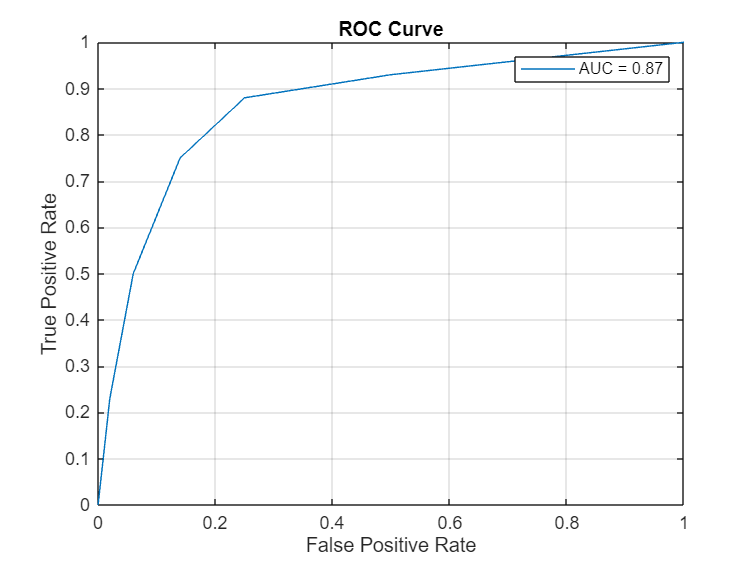

[X, Y, T, AUC] = perfcurve(class_test, scores(:, 2), 2);
figure;
plot(X, Y);
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title('ROC Curve');
legend(sprintf('AUC = %.2f', AUC));
grid on;


disp('ROC plot has been finished successfully');

ROC plot has been finished successfully


fprintf('TPR = %d\n', TPR);

TPR = 8.600000e-01


fprintf('FNR = %d\n', FNR);

FNR = 1.400000e-01


fprintf('TNR = %d\n', TNR);

TNR = 8.426966e-01


fprintf('FPR = %d\n', FPR);

FPR = 1.573034e-01


fprintf('Precision = %d\n', Precision);

Precision = 7.747748e-01


fprintf('Recall = %d\n', Recall);

Recall = 8.600000e-01


fprintf('F1 Score = %d\n', F1);

F1 Score = 8.151659e-01
